Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

Figura 1- Circuito base

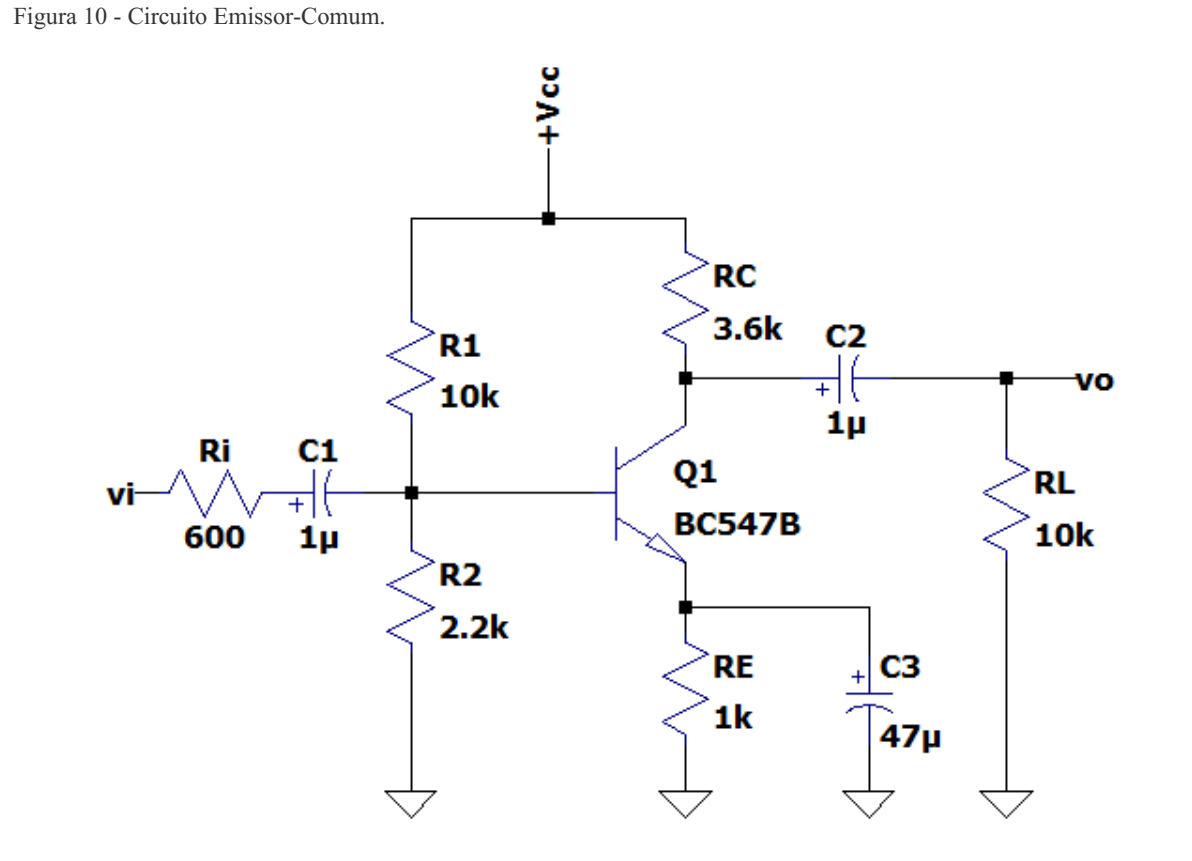

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

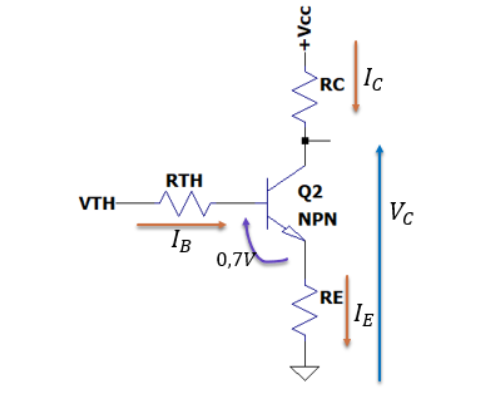

### Valores dos componentes:

R1 = 10e+3;%%Rth
R2 =2.2e+3;%%Rth
RE = 1e+3;%% R2+R3
Vcc = 10;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R2/(R1+R2))*Vcc

Vb = 1.8033

Rth = ((1/R1)+(1/R2))^-1

Ve = 1.0965

### Correntes

IB = (Vth-Vbe)/(Rth+RE*(B+1))

Vc = 6.0965

IC = (B+1)*IB
IE = IC

### Tensões CC

Vb = Vth
Ve = Vb-Vbe
Vc = Vce+Ve


## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

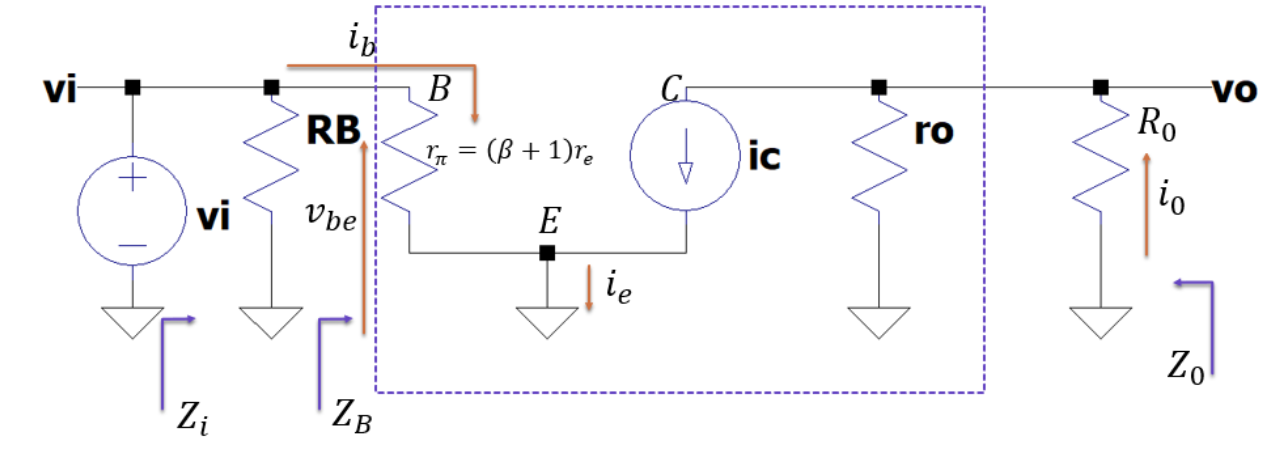

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 600; %valor de entrada da figura 1

R0 = 2.6471e+03

RL = 10e+3;%valor de entrada da figura 1
RC = 3.6e+3;%valor de entrada da figura 1

vi = 0.0100

RB = Rth; %calculado
R0 = ((1/RL)+(1/RC))^-1%calculado R0

re = 20.0641

VT = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q

rpi = 5.8387e+03

vi = 10e-3

### calculo do re e rpi:

re = VT/IE

Zb = 5.8219e+04

vb = 0.0074

rpi = (B+1)*re

### **Calculo para CA**

Zb = (B+1)*re

ib = 1.2789e-07

%ver como calc vb = 

ic = 3.7089e-05

ib = vb/Zb

ie = -3.7217e-05

Av = -9.8178

ic = B*ib

vo = -0.0982

Av = -R0/re%se ro>>R0 B>>1

Z0 = 2.6471e+03

ve = -0.0067

vc = -0.0982

vo = Av*vi

Zi = 1.9778e+03

Z0 = RL %ro>>RL
Zi = ((1/R1)+(1/R2)+(1/B*re))^-1